# Ejercicio 2

Cargamos la señal en dos variables.

senal = load('senal.dat');
t=senal(:,1);
y=senal(:,2);

Se calcula la transformada de fourier de la señal. Para observar mejor la transformada de plotea sobre unos ejes logaritmicos.

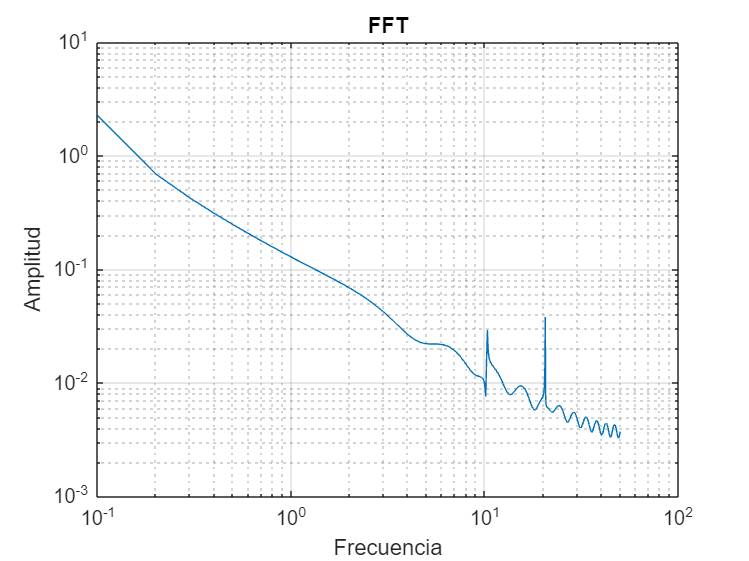

n=length(t);
fs = n/(t(end));
fft_mel=abs(fft(y,2^nextpow2(n)));
frec=linspace(0,fs/2,n/2+1);
fft_mel=fft_mel(1:length(frec))/n;%Nos quedamos solo con los datos de frecuencia positivos 
figure()
loglog(frec,fft_mel);
ylabel('Amplitud')
xlabel('Frecuencia')
title('FFT');
grid;

hold off

Se crea la ventana del filtro y se aplica sobre la señal ruidosa.

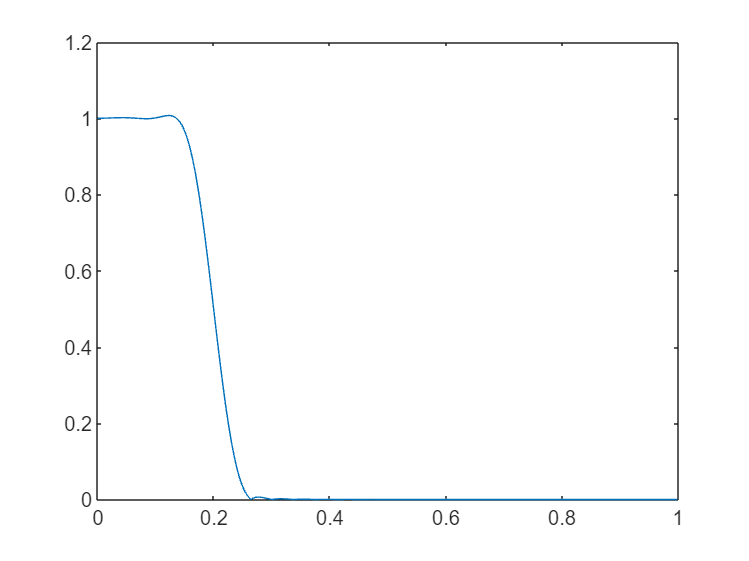

fc = 10/(fs/2);
N=50;
hw = hanning(N+1);
h = fir1(N,fc,hw);
[hw,wd]=freqz(h,1); plot(wd/pi,abs(hw));

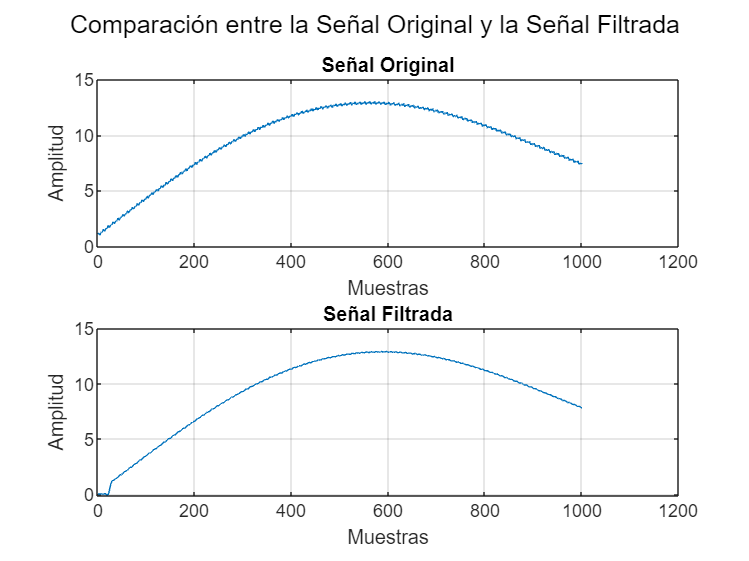


yf = filter(h,1,y);
figure;
subplot(2,1,1);
plot(y);
title('Señal Original');
xlabel('Muestras');
ylabel('Amplitud');
grid on;

subplot(2,1,2);
plot(yf);
title('Señal Filtrada');
xlabel('Muestras');
ylabel('Amplitud');
grid on;

% Mostrar las dos subtramas en la misma ventana
sgtitle('Comparación entre la Señal Original y la Señal Filtrada');

Implementación de un filtro móvil para emular el algoritmo que se podría implementar en un sistema empotrado.

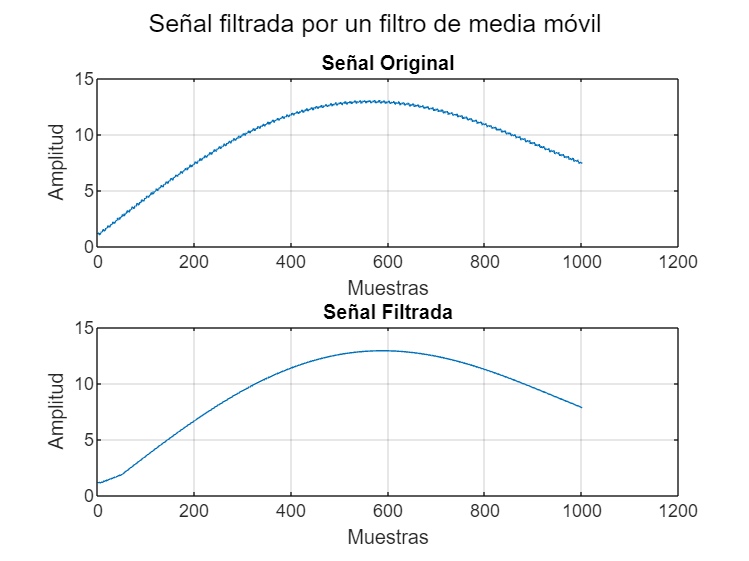

% Parámetros del filtro de media móvil
N = 50; % Longitud de la ventana de promedio móvil

% Implementación del filtro de media móvil
yf_real = zeros(size(n)); % Vector para almacenar la señal filtrada
for i = 1:length(y)
    if i <= N
        yf_real(i) = mean(y(1:i)); % Calcula el promedio de los primeros i elementos
    else
        yf_real(i) = mean(y(i-N+1:i)); % Calcula el promedio de los últimos N elementos
    end
end

% Graficar la señal de entrada y la señal filtrada
figure;
subplot(2,1,1);
plot(y);
title('Señal Original');
xlabel('Muestras');
ylabel('Amplitud');
grid on;

subplot(2,1,2);
plot(yf_real);
title('Señal Filtrada');
xlabel('Muestras');
ylabel('Amplitud');
grid on;

% Mostrar las dos subtramas en la misma ventana
sgtitle('Señal filtrada por un filtro de media móvil');

Se compara el espectro de frecuencias de la señal comparando los resultados de los dos métodos.

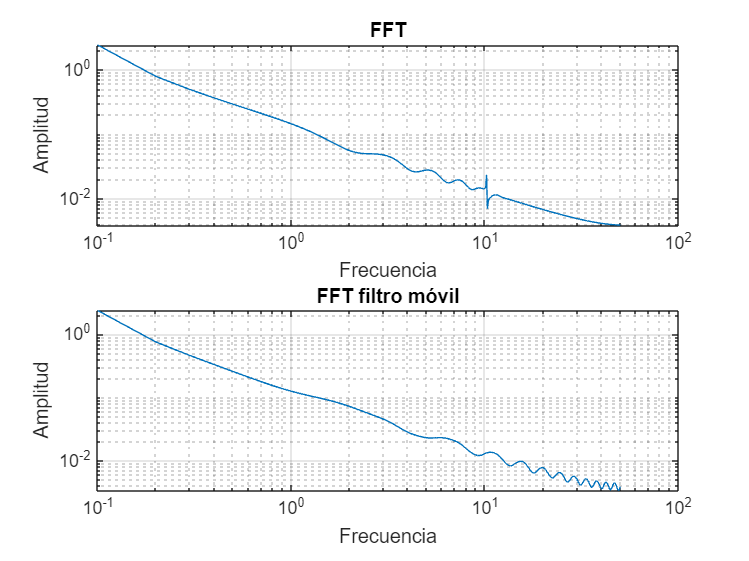

n=length(t);
fs = n/(t(end));
fft_mel=abs(fft(yf,2^nextpow2(n)));
fft_real=abs(fft(yf_real,2^nextpow2(n)));
frec=linspace(0,fs/2,n/2+1);
fft_mel=fft_mel(1:length(frec))/n;%Nos quedamos solo con los datos de frecuencia positivos 
fft_real=fft_real(1:length(frec))/n;
figure()
subplot(2,1,1);
loglog(frec,fft_mel);
ylabel('Amplitud')
xlabel('Frecuencia')
title('FFT');
grid;
subplot(2,1,2);
loglog(frec,fft_real);
ylabel('Amplitud')
xlabel('Frecuencia')
title('FFT filtro móvil');
grid on;
hold off